# Erzeugen vom Modell

## Erstellen eines Layer-Graphs

Erstelle ein Layer-Graph, das die Schichten vom Netzwerk enthält. Das Modell wurde durch die Anwendung "Deep Network Designer" entwurft.

lgraph = layerGraph();

## Hinzufügen von Schichten

tempLayers = [
    sequenceInputLayer([128,1,1],"Name","sequence")
    sequenceFoldingLayer("Name","seqfold")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 1],16,"Name","conv_1","Padding","same")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 1],"Name","maxpool_2","Padding","same")
    convolution2dLayer([3 1],32,"Name","conv_2","Padding","same")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 1],"Name","maxpool_1","Padding","same")];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    sequenceUnfoldingLayer("Name","sequnfold")
    flattenLayer("Name","flatten")
    lstmLayer(128,"Name","lstm")
    fullyConnectedLayer(256,"Name","fc_1")
    dropoutLayer(0.5,"Name","dropout_1")
    fullyConnectedLayer(128,"Name","fc_2")
    dropoutLayer(0.5,"Name","dropout_2")
    fullyConnectedLayer(4,"Name","fc_3")
    dropoutLayer(0.5,"Name","dropout_3")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

% clean up helper variable
clear tempLayers;

## Verbinden von Schichten

Verbinde Schicht-Teile miteinander

lgraph = connectLayers(lgraph,"seqfold/out","conv_1");
lgraph = connectLayers(lgraph,"seqfold/miniBatchSize","sequnfold/miniBatchSize");
lgraph = connectLayers(lgraph,"maxpool_1","sequnfold/in");

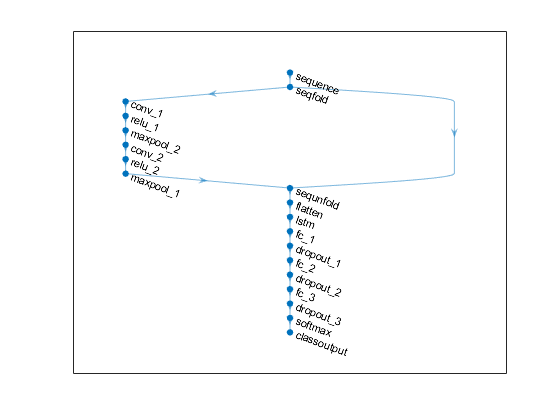

plot(lgraph);

lgraph =   LayerGraph with properties:

         Layers: [19×1 nnet.cnn.layer.Layer]
    Connections: [19×2 table]
     InputNames: {'sequence'}
    OutputNames: {'classoutput'}


lgraph = buildNetwork("cnn-lstm")

## Umformung und Vorverarbeitung der Daten

Extrahiere die in Keras vorverarbeitete Daten von der Mat-Datei 

Die Experimentart wird von der "userdependent"-Variable als Boolean eingesetzt; falls "true" eingestellt, dann werden %70 und %30 der Daten zufällig in bzw. Train- und Testdaten eingeteilt. Falls "false eingestellt", werden die Daten von 16 Teilnehmer für Train und der Rest für Testen verwendet.

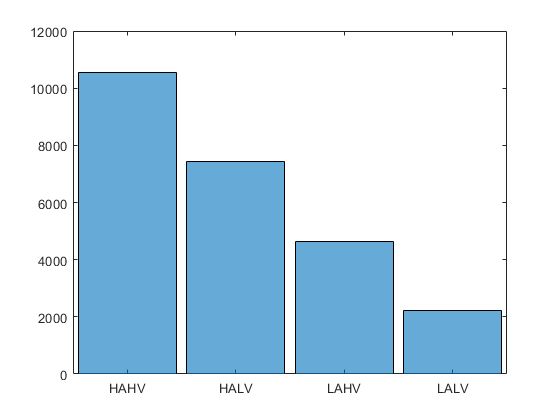

     HAHV      10560 
     HALV       7440 
     LAHV       4620 
     LALV       2220 


sampleList = 1×24840 cell array
  Columns 1 through 555

    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {128×1 double}    {12

categoriedLabels = 24840×1 categorical array
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 
     HAHV 


random_seed = 100;
userdependent = true;

[sampleList, categoriedLabels] = extractDataFromMatFile(Data)

[dataTrain, dataTest, labelTrain, labelTest] = prepareDatasetWithExperimentType(sampleList, categoriedLabels, userdependent, random_seed);
[trainDataLabel, testDataLabel] = arrayToCellArray(labelTrain, labelTest);

data_try = [];
for idx = 1:length(dataTrain)
    data_try = [data_try {[dataTrain{idx}']}];
end

label_try = [];
for idx = 1:length(labelTrain)
    label_try = [label_try {[labelTrain(idx)]}];
end

## Training the 1D-CNN-LSTM Network

to be edited

Training on single CPU.
|========================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Mini-batch  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |     Loss     |      Rate       |
|========================================================================================|
|       1 |           1 |       00:00:07 |       28.75% |       1.4417 |          0.0010 |
|       1 |          50 |       00:00:23 |       42.92% |       1.3097 |          0.0010 |
|       2 |         100 |       00:00:42 |       47.08% |       1.2886 |          0.0010 |
|       3 |         150 |       00:01:01 |       36.25% |       1.3227 |          0.0010 |
|       3 |         200 |       00:01:21 |       42.92% |       1.2670 |          0.0010 |
|       4 |         250 |       00:01:40 |       52.08% |       1.1758 |          0.0010 |
|       5 |         300 |       00:01:59 |       45.83% |       1.

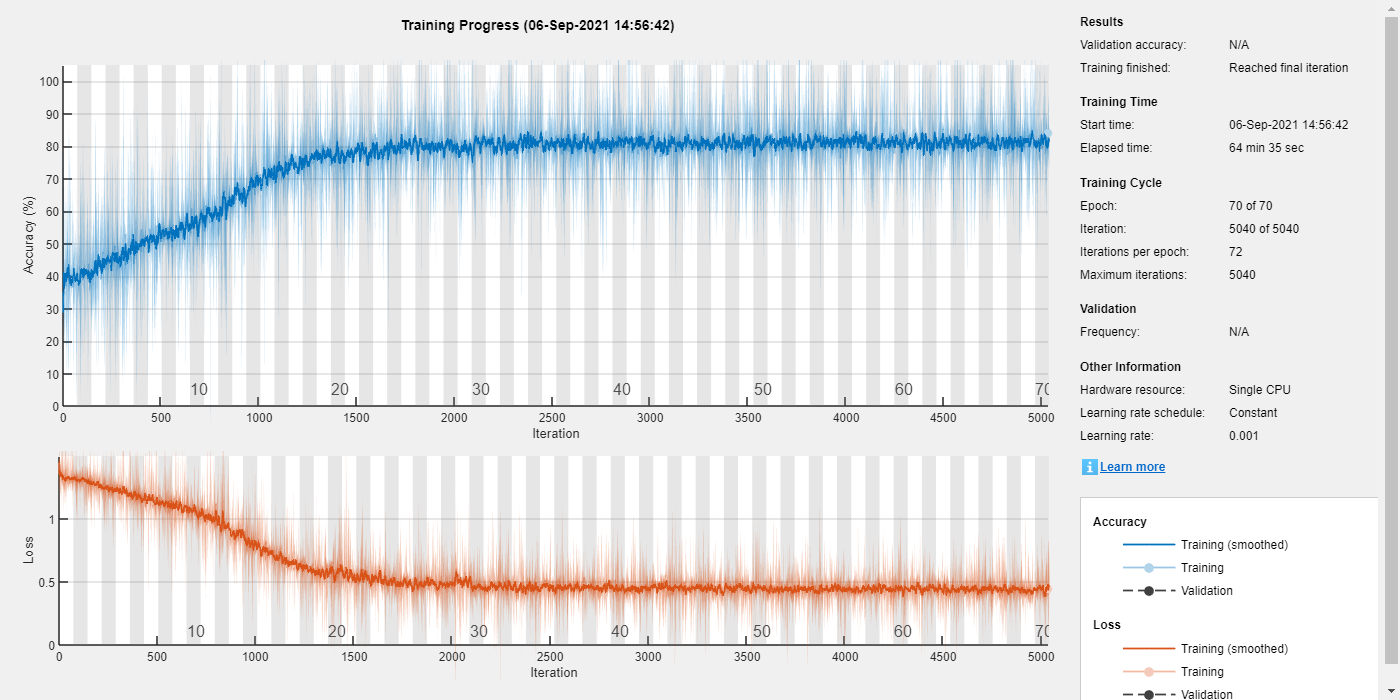

options = trainingOptions('adam', ...
    'MaxEpochs',70, ...
    'Verbose',true, ...
    'MiniBatchSize',240, ...
    'SquaredGradientDecayFactor', 0.99, ...
    'InitialLearnRate', 0.001, ...
    'Plots','training-progress');
net = trainNetwork(dataTrain,trainDataLabel,lgraph, options);

## Basic Evaluation of Trained Model

[trainPredictions, train_acc] = evaluateModel(net, dataTrain, labelTrain);

Accuracy: 0.99776


[testPredictions, test_acc] = evaluateModel(net, dataTest, labelTest);

Accuracy: 0.89801


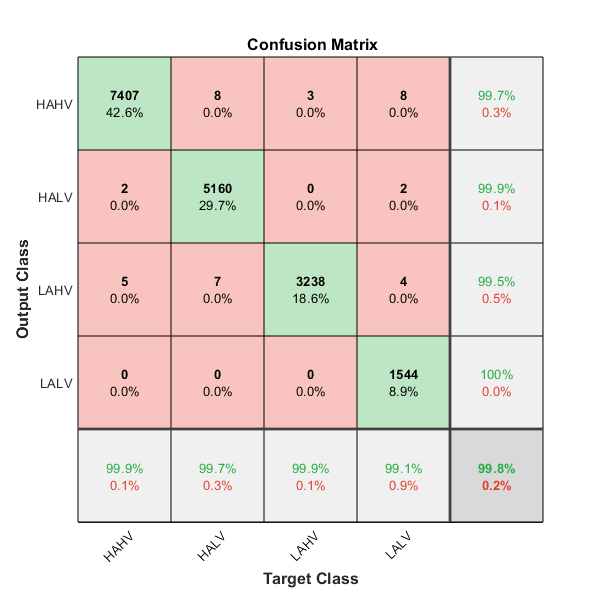

plotconfusion(labelTrain, trainPredictions)

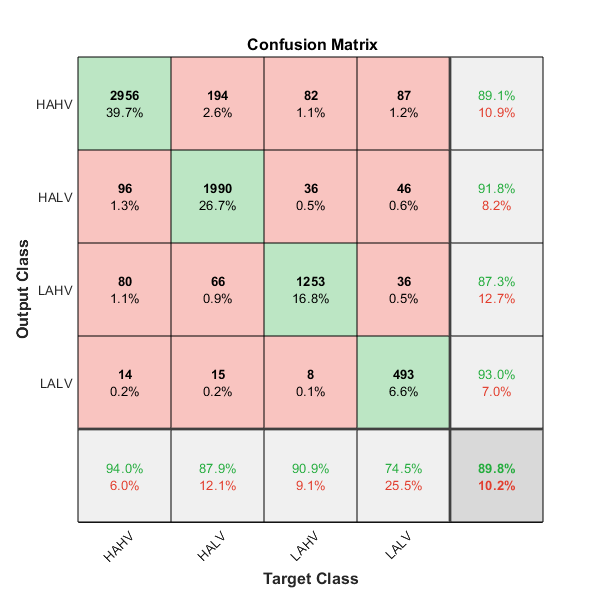

plotconfusion(labelTest, testPredictions)

## Export result

Results can be exported as mat-file for further evaluation with Python and Skitlearn library.

writeOutputToFile(trainPreds, labelTrain, testPreds, labelTest)

## Helper Functions for Formatting and Preprocessing

function lgraph = buildNetwork(networkType)
    if strcmp(networkType, "only-cnn") || strcmp(networkType, "cnn-lstm")
        inputSize = [128,1,1];
    elseif strcmp(networkType, "only-lstm")
        inputSize = 1;
    end
    
    lgraph = layerGraph();
    
    if strcmp(networkType, "cnn-lstm")
        tempLayers = [
            sequenceInputLayer(inputSize,"Name","sequence")
            sequenceFoldingLayer("Name","seqfold")];
        lgraph = addLayers(lgraph,tempLayers);
    elseif strcmp(networkType, "only-lstm")
        tempLayers = [
            sequenceInputLayer(inputSize,"Name","sequence")];
        lgraph = addLayers(lgraph,tempLayers);
    elseif strcmp(networkType, "only-cnn")
        tempLayers = [
            imageInputLayer(inputSize, "Name", "image")];
        lgraph = addLayers(lgraph,tempLayers);
    end
    
    if strcmp(networkType, "only-cnn") || strcmp(networkType, "cnn-lstm")
        tempLayers = [
            convolution2dLayer([3 1],16,"Name","conv_1","Padding","same")
            reluLayer("Name","relu_1")
            maxPooling2dLayer([2 1],"Name","maxpool_2","Padding","same")
            convolution2dLayer([3 1],32,"Name","conv_2","Padding","same")
            reluLayer("Name","relu_2")
            maxPooling2dLayer([2 1],"Name","maxpool_1","Padding","same")];
        lgraph = addLayers(lgraph,tempLayers);
    end
    
    if strcmp(networkType, "cnn-lstm")
        tempLayers = [
            sequenceUnfoldingLayer("Name","sequnfold")
            flattenLayer("Name","flatten")
            lstmLayer(128,"Name","lstm")];
        lgraph = addLayers(lgraph,tempLayers);
    elseif strcmp(networkType, "only-lstm")
        tempLayers = [
            lstmLayer(128,"Name","lstm")];
        lgraph = addLayers(lgraph,tempLayers);
    end
    tempLayers = [
        fullyConnectedLayer(256,"Name","fc_1")
        dropoutLayer(0.5,"Name","dropout_1")
        fullyConnectedLayer(128,"Name","fc_2")
        dropoutLayer(0.5,"Name","dropout_2")
        fullyConnectedLayer(4,"Name","fc_3")
        dropoutLayer(0.5,"Name","dropout_3")
        softmaxLayer("Name","softmax")
        classificationLayer("Name","classoutput")];
    lgraph = addLayers(lgraph,tempLayers);
    
    if strcmp(networkType, "cnn-lstm")
        lgraph = connectLayers(lgraph,"seqfold/out","conv_1");
        lgraph = connectLayers(lgraph,"seqfold/miniBatchSize","sequnfold/miniBatchSize");
        lgraph = connectLayers(lgraph,"maxpool_1","sequnfold/in");
        lgraph = connectLayers(lgraph, "lstm", "fc_1");
    elseif strcmp(networkType, "only-lstm")
        lgraph = connectLayers(lgraph, "sequence", "lstm");
        lgraph = connectLayers(lgraph, "lstm", "fc_1");
    elseif strcmp(networkType, "only-cnn")
        lgraph = connectLayers(lgraph, "image", "conv_1");
        lgraph = connectLayers(lgraph, "maxpool_1", "fc_1");
    end
    
    plot(lgraph);
    clear tempLayers;
end

function [sampleList, categoriedLabels] = extractDataFromMatFile(data_var)
    sampleList = [];
    labelList = [];
    flag = true;
    for subjectIndex = 1:length(data_var)
        subject = data_var{subjectIndex};
        for experimentIndex = 1:length(subject)
            experiment = subject{experimentIndex};
            segmentList = experiment{1,1};
            sampleList = [sampleList, segmentList];
            for segmentIndex = 1:length(segmentList)
               label = string(experiment{2});
               labelList = [labelList, label]; 
            end
        end
    end
    categoriedLabels = categorical(labelList');
    histogram(categoriedLabels)
    summary(categoriedLabels)
end

function [trainDataLabel, testDataLabel] = arrayToCellArray(trainLabel, testLabel)
    trainDataLabel = [];
    for sample = 1:length(trainLabel)
        trainDataLabel = [trainDataLabel; {[trainLabel(sample)]}];
    end
    
    testDataLabel = [];
    for sample = 1:length(testLabel)
        testDataLabel = [testDataLabel; {[testLabel(sample)]}];
    end
end

function [dataTrain, dataTest, labelTrain, labelTest] = prepareDatasetWithExperimentType(sampleList, categoriedLabels, userdependent, random_seed)
    if userdependent
        % Cross validation (train: 70%, test: 30%)
        cv = cvpartition(length(categoriedLabels),'HoldOut',0.3);
        idx = cv.test;
        % Separate to training and test data
        dataTrain = sampleList(:,~idx)';
        dataTest  = sampleList(:,idx)';
        labelTrain = categoriedLabels(~idx,:);
        labelTest = categoriedLabels(idx,:);
    else
        numOfSamples = 16*18*60;
        dataTrain = sampleList(:,1:num_of_samples);
        dataTest = sampleList(:,num_of_samples:length(sampleList));
        labelTrain = categoriedLabels(1:numOfSamples,:);
        labelTest = categoriedLabels(numOfSamples:length(categoriedLabels));
    end
end

function [predictions, acc] = evaluateModel(net, testData, testLabel)
    preds = net.classify(testData);
    predictions = [];
    for pred = 1:length(preds)
        predictions = [predictions; preds{pred}];
    end
    acc = sum(predictions == testLabel) / numel(testLabel);
    disp(['Accuracy: ', num2str(acc)])
end

function writeOutputToFile(trainPreds, labelTrain, testPreds, labelTest)
    trainOutput = [cellstr(trainPreds), cellstr(labelTrain)];
    testOutput = [cellstr(testPreds), cellstr(labelTest)];
    combinedOutputs = {trainOutput, testOutput};
    save("outputs", "combinedOutputs")
end